# ENME462 Studio3

by Xie Zheng

Section 0101 W 1:00PM - 2:50PM; Section 0103 F 10:00AM - 11:50AM

Github: [https://github.com/XieGT/Control_Studios](https://github.com/XieGT/Control_Studios)

Email: enme462fall2018@gmail.com

The first objective of this studio is to reinforce dynamic modeling of mechanical and electrical systems covered in lectures. The second objective is to utilize MATLAB to solve for the required transfer function from the obtained equations.

## 3.1. Automobile Suspension System

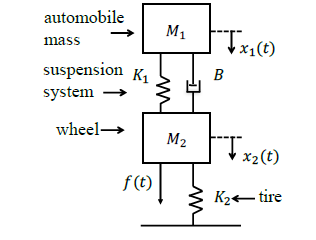

Governing equations


$$M_1\ddot{x}_1(t)=-K_1\left(x_1(t)-x_2(t)\right)-B\left(\dot{x}_1(t)-\dot{x}_2(t)\right)\\
M_2\ddot{x}_2(t)=-K_2x_2-K_1\left(x_2(t)-x_1(t)\right)-B\left(\dot{x}_2(t)-\dot{x}_1(t)\right)+f(t)$$


Laplace transformation with 0 initial conditions


$$M_1s^2X_1(s)=-K_1\left(X_1(s)-X_2(s)\right)-Bs\left(X_1(s)-X_2(s)\right)\\
M_2s^2X_2(s)=-K_2X_2(s)-K_1\left(X_2(s)-X_1(s)\right)-Bs\left(X_2(s)-X_1(s)\right)+F(s)$$


Equation of motion in the Lapalce domain


$$(M_1s^2+Bs+K_1)X_1(s)-(Bs+K_1)X_2(s)=0\\
-(Bs+K_1)X_1(s)+(M_2s^2+Bs+K_1+K_2)X_2(s)=F(s)
$$


Matrix form


$$\left[ {\begin{array}{cc}
   M_1s^2+Bs+K_1 & -(Bs+K_1) \\
   -(Bs+K_1) & M_2s^2+Bs+K_1+K_2 \\
  \end{array} } \right] \cdot 
\left[ {\begin{array}{cc}
   X_1(s) \\
   X_2(s)
\end{array} } \right] =
\left[ {\begin{array}{cc}
   0 \\
   F(s)
\end{array} } \right]
$$


## 3.2. Flexible Transmission in Robotic Systems

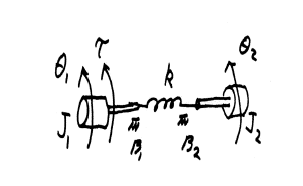

Governing equations


$$J_1\ddot{\theta}_1(t)=-K\left(\theta_1(t)-\theta_2(t)\right)-B_1\dot{\theta}_1(t)+\tau(t)\\
J_2\ddot{\theta}_2(t)=-K\left(\theta_2(t)-\theta_1(t)\right)-B_2\dot{\theta}_2(t)$$


Laplace transformation with 0 initial conditions


$$J_1s^2\theta_1(s)=-K\left(\theta_1(s)-\theta_2(s)\right)-B_1s\theta_1(s)+\tau(s)\\
J_2s^2\theta_2(s)=-K\left(\theta_2(s)-\theta_1(s)\right)-B_2s\theta_2(s)$$


Equation of motion in Laplace domain


$$\left(J_1s^2+B_1s+K\right)\theta_1(s)-K\theta_2(s)=\tau(s)\\
\left(J_2s^2+B_2s+K\right)\theta_2(s)-K\theta_1(s)=0$$


Matrix form


$$\left[ {\begin{array}{cc}
   J_1s^2+B_1s+K & -K \\
   -K & J_2s^2+B_2s+K \\
  \end{array} } \right] \cdot 
\left[ {\begin{array}{cc}
   \theta_1(s) \\
   \theta_2(s)
\end{array} } \right] =
\left[ {\begin{array}{cc}
   \tau(s) \\
   0
\end{array} } \right]
$$


## 3.3. Electrical Circuits

Given the electric circuit below, sho that the transfer function I2(s)/V(s) is of the form given in the block diagram.

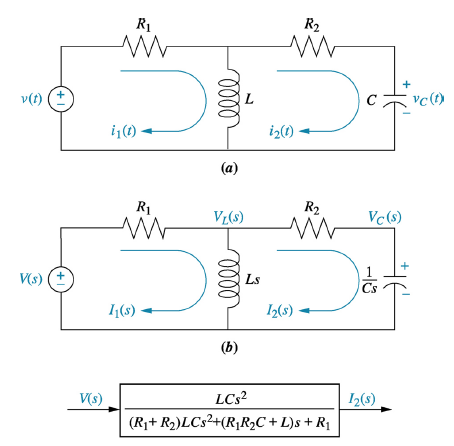

Electrical Impedance

- Resistor:            $V_R(t)=R\cdot i(t) \qquad V_R(s)=R\cdot I(s)$

- Inductor:            $V_L(t)=L\cdot\frac{di}{dt} \qquad   V_L(s)=Ls\cdot I(s)$

- Capacitor:         $V_c(t)=\frac{1}{C}\cdot\int idt \qquad V_C(s)=\frac{1}{Cs}\cdot I(s)$

First mesh


$$R_1(s)I_1(s)+Ls\left(I_1(s)-I_2(s)\right)=V(s)$$


Second mesh


$$R_2(s)I_2(s)+\frac{1}{Cs}I_2(s)=Ls\left(I_1(s)-I_2(s)\right)$$


Matrix form


$$\left[ {\begin{array}{cc}
   R_1+Ls& -Ls \\
   -Ls & Ls+R_2+\frac{1}{Cs} \\
  \end{array} } \right] \cdot 
\left[ {\begin{array}{cc}
   I_1(s) \\
   I_2(s)
\end{array} } \right] =
\left[ {\begin{array}{cc}
   V(s) \\
   0
\end{array} } \right]
$$


## Cramer's rule

For system of n linear equations 


$$\begin{array}{c}
a_{11}x_1+a_{12}x_2 +a_{1n}=b_1\\
a_{21}x_1+a_{22}x_2 +a_{2n}=b_2\\
...\\
a_{n1}x_1+a_{n2}x_2 +a_{nn}=b_n\\
\end{array}\\$$


Vector-matrix form


$$Ax=B$$


where


$$A=\left[\begin{array}{cccc}
a_{11} & a_{12} & ... & a_{1n}\\
a_{21} & a_{22} & ... & a_{2n}\\
... & ... & ... & ...\\
a_{n1} & a_{n2} & ... & a_{nn}
\end{array} \right] \qquad
B=\left[\begin{array}{c}
b_{1} \\
b_{2} \\
...\\
b_{n}
\end{array} \right] \qquad
x=\left[\begin{array}{c}
x_{1} \\
x_{2} \\
...\\
x_{n}
\end{array} \right] \\$$


Cramer's Rule 


$$x_k=\frac{\det {A_k}}{\det{A}}$$


where A_k is a matrix formed by replacing kth column of A by B

for 3.3 


$$A=\left[\begin{array}{cc}
R_1+Ls& -Ls \\
   -Ls & Ls+R_2+\frac{1}{Cs} \\
\end{array} \right] \qquad
B=\left[\begin{array}{c}
 V(s) \\
   0
\end{array} \right] \qquad
x=\left[\begin{array}{c}
 I_1(s) \\
 I_2(s)
\end{array} \right] \\
$$



$$A_1=\left[\begin{array}{cc}
V(s) & -Ls \\
   0 & Ls+R_2+\frac{1}{Cs} \\
\end{array} \right] \qquad
A_2=\left[\begin{array}{cc}
R_1+Ls& V(s) \\
   -Ls & 0 \\
\end{array} \right]$$



$$I_1(s)=\frac{\det (A_1)}{\det (A)} \qquad
I_2(s)=\frac{\det (A_2)}{\det (A)}$$


## 3.4 Matlab Code: ch2sp4.m

'(ch2sp4) Example 2.10'       % Display label.

ans = (ch2sp4) Example 2.10

syms s R1 R2 L c V            % Construct symbolic objects for frequency
                              % variable 's', and 'R1', 'R2', 'L', 'c', and 'V'.
                              % Note: Use lower-case "c" in declaration for 
                              % capacitor.
A2=[(R1+L*s) V;-L*s 0]        % Form Ak = A2.

$$A2 = \left(\begin{array}{cc} R_{1}+L\,s & V\\ -L\,s & 0 \end{array}\right)$$

A=[(R1+L*s) -L*s;-L*s (L*s+R2+(1/(c*s)))]

$$A = \left(\begin{array}{cc} R_{1}+L\,s & -L\,s\\ -L\,s & R_{2}+L\,s+\frac{1}{c\,s} \end{array}\right)$$

                              % Form A.
I2=det(A2)/det(A);            % Use Cramer's rule to solve for I2(s).
I2=simplify(I2);              % Reduce complexity of I2(s).
G=I2/V;                       % Form transfer function, G(s) = I2(s)/V(s).
'G(s)'                        % Display label.

ans = G(s)

pretty(G)                     % Pretty print G(s).

                        2
                   L c s
--------------------------------------------
                   2           2
R1 + L s + L R1 c s  + L R2 c s  + R1 R2 c s



## MATLAB Exercises

**Exercise 1.** Make a copy of the file ch2sp4.m and change the file name to stuido3exc1.m. Modify this file by utilizing results obtained in Part 3.1 (the Automobile Suspension System) to obtain the transfer function T(s) = X1(s)/F(s).That is, the transfer function between the vertical height of the vehicle and the disturbance on the road.

**Exercise 2.** Make a copy of the file ch2sp4.m and change the file name to stuido3exc2.m. Using results obtained in Part 3.2 (Flexible Transmission in Robotic Systems), obtain the following transfer functions


$$(a)T_1(s)=\frac{\theta_1(s)}{\tau(s)} \qquad 
(b)T_2(s)=\frac{\theta_2(s)}{\tau(s)}$$


**Exercise 3.** Write a Matlab script or use Simulink to simulate the angular displacement response of an armature-controlled DC servo-motor due to a voltage input shown below. The model of an armature-controlled DC motor is given by:


$$\frac{\theta(s)}{E_a(s)}=\frac{K}{s(s+a)}$$


Assume that a=K=1. Present angular displacement $\theta(t)$ and angular velocity $\omega(t)$ responses and explain to the TA what the responses physically mean.

Hint: If you choose to write a script, one way is to use lsim(system,input,time) in MATLAB.